# Generating single sample gene regulatory networks using LIONESS

**Author:**

Marouen Ben Guebila

## Generation of single sample networks

PANDA [1] (Passing Attributes Between Networks for Data Assimilation) allows building gene regulatory networks using 1) motif prior networks, 2) PPI networks, and 3) gene coexpression networks. The latter is built on a set of gene expression measurments over many samples. In some applications, we could be interested in analyzing the network from a single sample rather than all samples like PANDA does. Since it could be challenging to built a coexpression network using a single sample, LIONESS [2] infers the single sample network $l_i$ from the original PANDA network $p$ through linear interpolation of the estimated PANDA networks without the $i^{\mathrm{th}}$ sample $p_i$.

                                                                                            
$$l_i =N_{\mathrm{samples}} *\left(p-p_i \right)+p_i$$


, where $p,p_i ,\mathrm{and}\;l_i$ are regulatory networks represented as TF-by-gene matrices.

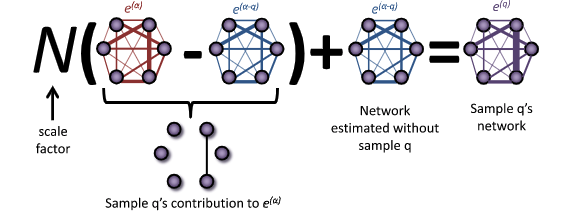

### Using LIONESS to infer single sample gene regulatory networks

For this tutorial, we will reconstruct a single sample gene regulatory network using toy data and the LIONESS function implemented in the netZooM package of network biology methods.

### Install netZooM

You can git clone [https://github.com/netZoo/netZooM.git](https://github.com/netZoo/netZooM.git) to your local directory. Then add it in your MATLAB path.

addpath(genpath('path/to/netZooM'))

### Set the parameters

LIONESS typically uses the outout data from PANDA. To save all intermediate files in PANDA make sure to call PANDA with the save_temp option set to a folder path. In this case, we saved PANDA output to test_data folder. Like PANDA, LIONESS uses the expression network, the motif network, and the ppi network. In this case, we will use the updated networks after a PANDA run.

exp_file   = 'test_data/expression.transposed.mat';
motif_file = 'test_data/motif.normalized.mat';
ppi_file   = 'test_data/ppi.normalized.mat';

LIONESS also requires the final PANDA network, a learning rate alpha of 0.1 is usually recommended for most applications, START and END refer to the sample indices we would like to reconstruct.

panda_file = 'panda2.test.mat'; % This test network has been transposed
% to test savePairs, so we need to tranpose it back
load('test_data/panda.test.mat');
AgNet      = AgNet';
save('panda2.test.mat','AgNet');
alpha      = 0.1;
START      = 1;  % sample-of-interest starting from this index
END        = 1;  % sample-of-interest ending to this index; use -1 to end at the last sample
ascii_out  = 0;  % set to 1 if you prefer text output file instead of MAT-file
save_dir   = 'test_data';
lib_path   = '../netZooM';

### Running LIONESS

Now, we call LIONESS using the lioness_run function. LIONESS does not output an enviroment variable but saves all the START-END+1 networks in files.

lioness_run(exp_file, motif_file, ppi_file, panda_file, save_dir, START, END, alpha, ascii_out, lib_path);

01-Jul-2019 17:02:12
Input expression file: test_data/expression.transposed.mat
Input motif file: test_data/motif.normalized.mat
Input PPI file: test_data/ppi.normalized.mat
Input PANDA network: panda2.test.mat
Output LIONESS folder: test_data
Sample index: 1 - 1
Alpha: 0.10
ASCII output: 0
Reading in expression data!
1000 genes and 50 conditions!
Elapsed time is 0.009887 seconds.
Reading in motif data!
Elapsed time is 0.008781 seconds.
Reading in ppi data!
Elapsed time is 0.008220 seconds.
Reading in PANDA network!
Elapsed time is 0.040858 seconds.
Running LIONESS for sample 1:
Computing coexpresison network:
Elapsed time is 0.089737 seconds.
Normalizing Networks:
Elapsed time is 0.062384 seconds.
Running PANDA algorithm:
Learning Network!
Step#0, hamming=1.0303
Step#1, hamming=0.38296
Step#2, hamming=0.28008
Step#3, hamming=0.23643
Step#4, hamming=0.20903
Step#5, hamming=0.18723
Step#6, hamming=0.16782
Step#7, hamming=0.14976
Step#8, hamming=0.1328
Step#9, hamming=0.11698
Step#10, ha

Since we requires only START-END+1 = 1-1+1 = 1 network, LIONESS generated one network, that is the network for the first sample.

We check this network in test_data folder

cd test_data
load('lioness.1.mat');
size(PredNet)

The first sample, just like the original PANDA toy network, has 661 TF by 1000 gene.

### References

[1] Glass, Kimberly, et al. "Passing messages between biological networks to refine predicted interactions." *PloS one* 8.5 (2013): e64832.

[2] Kuijjer, Marieke Lydia, et al. "Estimating sample-specific regulatory networks." *iScience* 14 (2019): 226-240.